# Project 2

Ross Smyth

clc, clear, close all

## Summary

This report will go over Project 2 from MEEM 4730. This project aims at developing a model of a simple rocket in Simulink using base Simulink structures, and a model using Simscape structures, verifying them, and then comparing the results for more complicated situations. The following steps were followed:

- Develop differential equation model

- Implement Simulink model of differential equations

- Implement Simscape model

- Find closed form solution of simple situation at burn out for verification

- Simulate more complicated situation without closed-form solution, compare two models

## Derivation

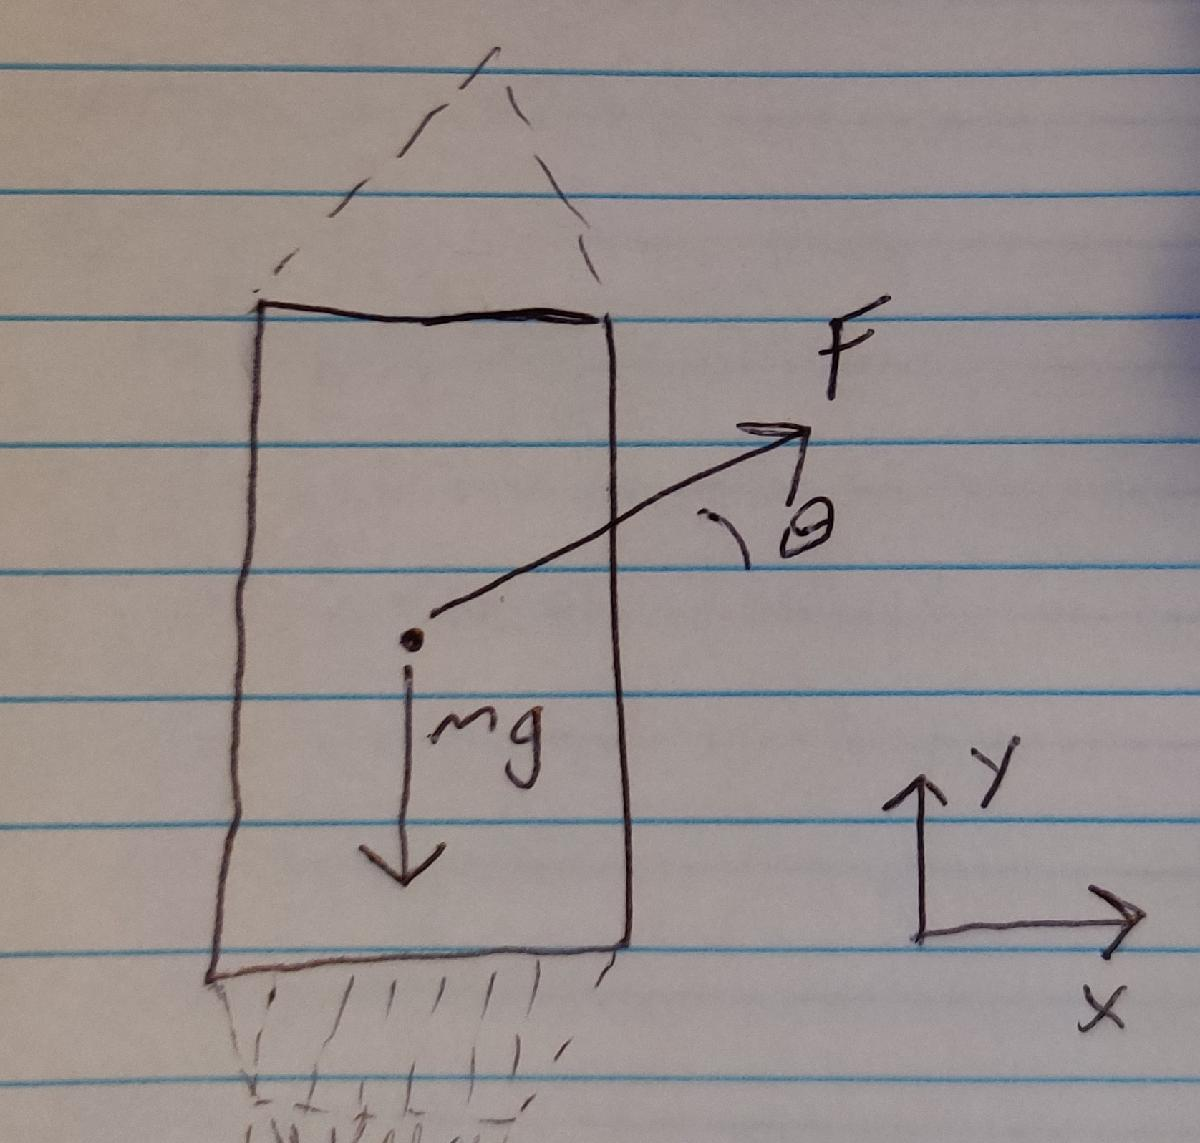

The rocket is assumed to be a point mass, and air resistance is assumed to be negligible.

From the free-body diagrma above, the following force expressions can be developed:


$$\begin{array}{l}
{\mathrm{ma}}_x =F\left(t\right)\;\mathrm{cos}\left(\theta \left(t\right)\right)\\
a_x =\frac{F\left(t\right)}{m}\mathrm{cos}\left(\theta \left(t\right)\right)
\end{array}$$



$$\begin{array}{l}
{\mathrm{ma}}_y =F\left(t\right)\;\mathrm{sin}\left(\theta \left(t\right)\right)-m\;g\\
a_y =\frac{F\left(t\right)}{m}\mathrm{sin}\left(\theta \left(t\right)\right)-\;g
\end{array}$$


Afterwards, the states for the model can be set:


$$\begin{array}{l}
x_1 =x\\
x_2 =y\\
x_3 =\dot{x} \\
x_4 =\dot{y} 
\end{array}$$


Then the derivatives can be inserted from the force expressions to get the state-variables reprsentation.


$$\begin{array}{l}
\dot{x_1 } =x_3 \\
\dot{x_2 } =x_4 \\
\dot{x_3 } =\frac{F}{m}\;\mathrm{cos}\left(\theta \left(t\right)\right)\\
\dot{x_4 } =\frac{F}{m}\;\mathrm{sin}\left(\theta \left(t\right)\right)-g
\end{array}$$


If represented in a more traditional matrix-like form:


$$\dot{\overrightarrow{x} } =\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \overrightarrow{x} +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
\frac{\mathrm{cos}\left(\theta \left(t\right)\right)}{m} & 0\\
\frac{\mathrm{sin}\left(\theta \left(t\right)\right)}{m} & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
F\\
g
\end{array}\right\rbrack$$


## Simulink Models

### Base Simulink

This model directly implements the above derivation into a Simulink construct. This was done by creating a Matlab function in the model that took in the states of the mode, calculated the derivatives from the states using the above differential equations, then integrated the output.

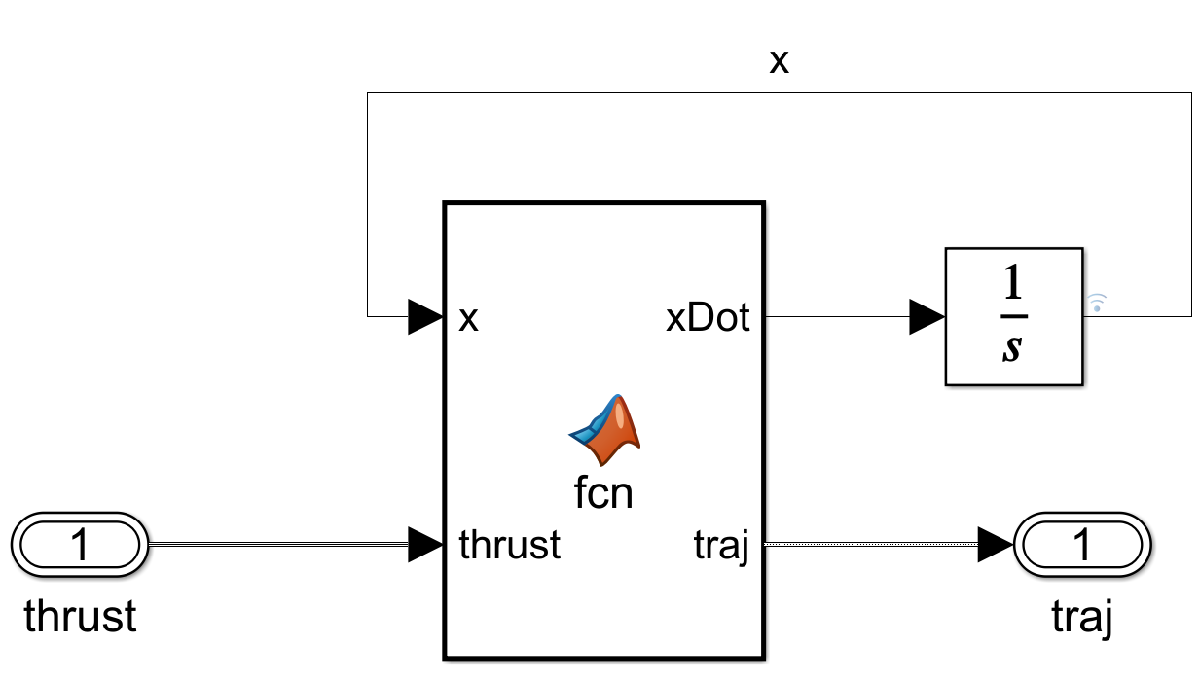

### Simscape

This model indirectly implements the derived model. It more of a graphical way of thinking, rather than a mathematical way. Reference frames are defined, then constraints and joints are palced between them. In this case there are two frames:

- The Earth

- The rocket

The frames are joiend with a recangular joint, which has two prismatic portions to it that are orthogonal to each other. This joint does not have rotation as the rocket is assumed a point mass. A force vector from the thrust is applied to the rocket, and gravity is a part of the simulation.

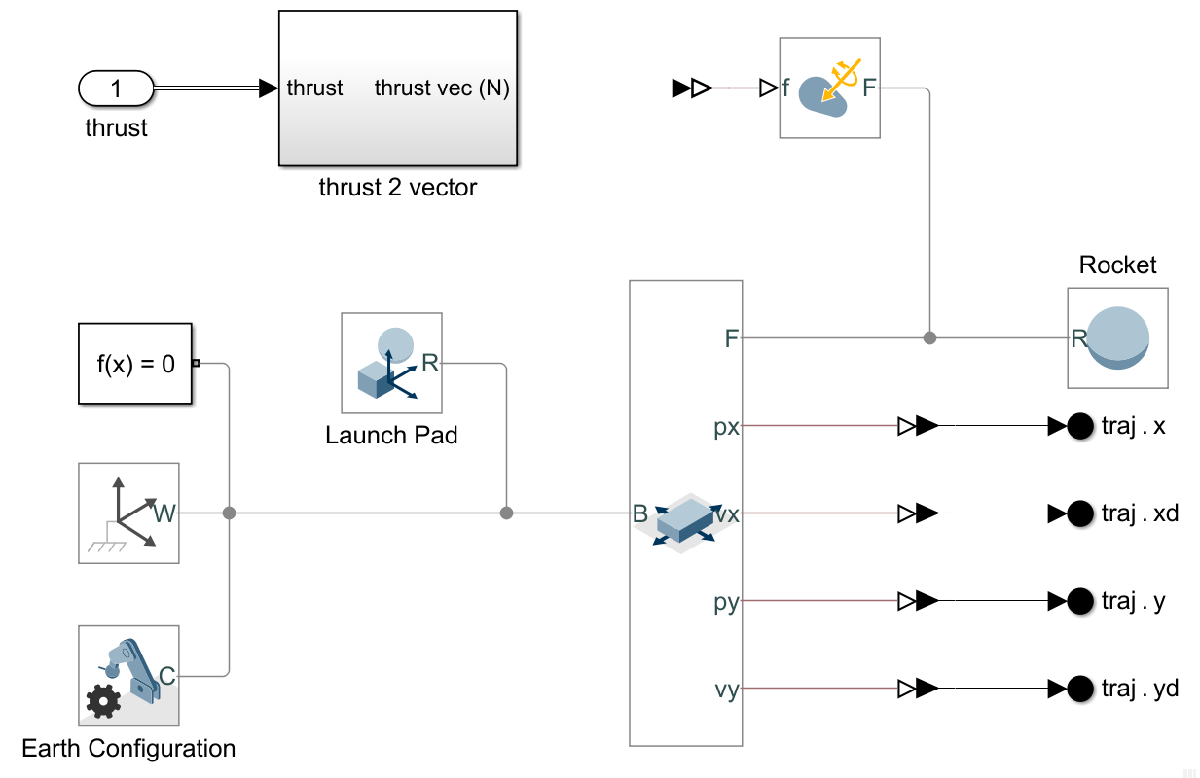

## Closed-form

For the closed form solution, the following parameters were used:

- Thrust = 15000N

- Thrust Angle = 56 Degrees

- Mass = 1000 kg

- Initial conditions = $\overrightarrow{0}$

- Burn time = 5 seconds

- Gravity = 10 m/s/s

From this conditions, a closed-form solution can be developed. All that is done is the above equations are integrated from zero to five seconds. 


$$\vec{x} =\int_0^5 \dot{\overrightarrow{x} }$$



$$\dot{y} \left(5\right)=\left(\frac{15000}{1000}\mathrm{sin}\left(56\right)-10\right)t=12\ldotp 17781\;\frac{m}{s}$$



$$y\left(5\right)=\frac{1}{2}\left(\frac{15000}{1000}\mathrm{sin}\left(56\right)-10\right)t^2 =30\ldotp 44454\;m$$



$$\dot{x} \left(5\right)=\left(\frac{15000}{1000}\mathrm{cos}\left(56\right)\right)t=41\ldotp 93946\;\frac{m}{s}$$



$$x\left(5\right)=\frac{1}{2}\left(\frac{15000}{1000}\mathrm{cos}\left(56\right)\right)t^2 =104\ldotp 84866\;m$$


## Verification

After the closed form solutions were found above, they were compared with the output from the base Simulink model. Another form of verification used was ensuring that after burnout of the rocket energy was conserved. The closed form solution was also used to find an accepable integration technique. Finally, the models were verified via energy conservation and against each other with a time-varying thrust scenario.

### Closed-form Comparison

run("rocketSimSetup.m");

 *** BURNOUT STATE COMPARISON *** 
 State  Unit  Closed Form  Simulated     Error 
 ----------------------------------------------- 
   x     m      +104.85     +104.85    1.279e-13     
   y     m       +30.44      +30.44    5.684e-14     
  xd   m/s       +41.94      +41.94    2.416e-13     
  yd   m/s       +12.18      +12.18    1.208e-13     


close all;

As can be seen above, the error between the closed form solutions and the model is very low. This is between the closed-form and the base Simulink model. Below shows the difference between the base Simulink and the Simscape models' y coordinate with time.

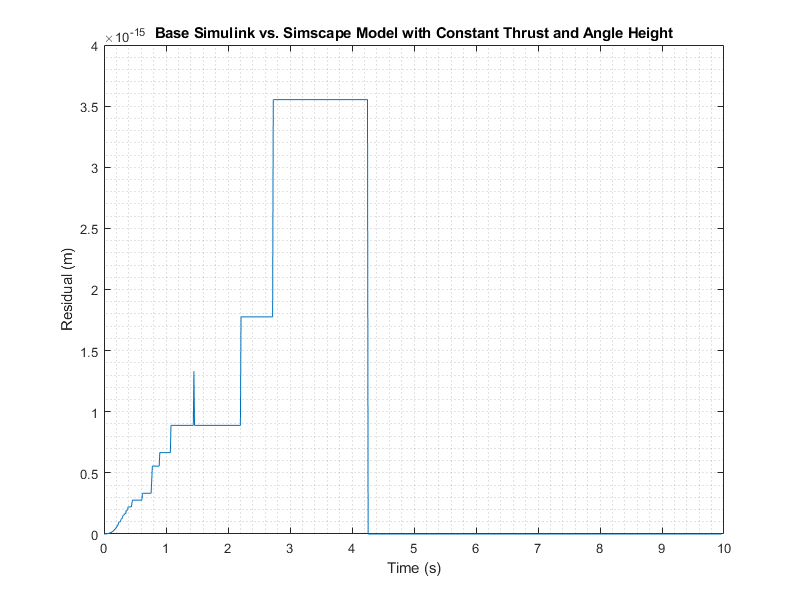

figure("Position",[0, 0, 800, 600])
% matlab will cover up the scientific notation of the y axis if it is larger. Excellent design mathworks.
plot(s1.out.sdat{1}.Values.y-s1.out.sdat{2}.Values.y)
title("Base Simulink vs. Simscape Model with Constant Thrust and Angle Height")
ylabel("Residual (m)")
xlabel("Time (s)")
grid minor

As can be seen, the error between the two models is extremly small, much smaler than the error of the base Simulink model, meaning that both models have less than ${\mathrm{x10}}^{-10}$ meters of error to the closed-form solution.

### Energy Conservation

Below shows the energy vs time for both models post-burnout.

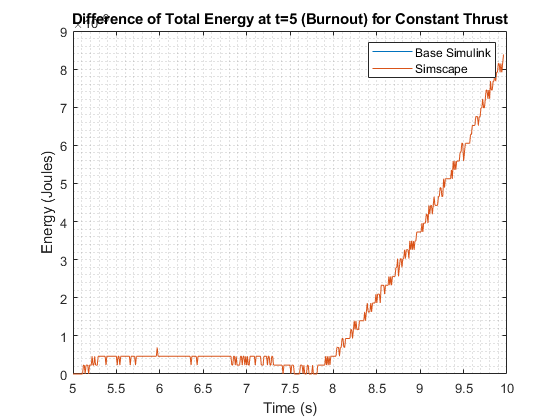

figure("Position",[0, 0, 900, 600])
% This time the figure wouldn't even change size for me :(

[energyDQ, energySC] = energy(s1);

tEN      =     s1.t(s1.t >= 5);
energyDQ = energyDQ(s1.t >= 5);
energySC = energySC(s1.t >= 5);

figure()
plot(tEN, energyDQ - energyDQ(1), tEN, energySC - energySC(1))
legend("Base Simulink", "Simscape")
xlabel("Time (s)")
ylabel("Energy (Joules)")
grid minor
title("Difference of Total Energy at t=5 (Burnout) for Constant Thrust")

As can be seen above, after the burnout of the rocke the energy change by a maximum of approximatly $9{\mathrm{x10}}^{-9}$ Joules. This is minimal, and is within a reasonable amount of error for this simulation. The cumulative RSS error of the energy with the energy at burnout can be seen below for both models:

base_simulink_cumulative_energy_error_constant = sqrt(sum((energyDQ - energyDQ(1)).^2))

base_simulink_cumulative_energy_error_constant = 6.3909e-08

simscape_cumulative_energy_error_constant = sqrt(sum((energySC - energySC(1)).^2))

simscape_cumulative_energy_error_constant = 6.3909e-08

### Integration Tuning

After verification, the Simulink integrator used was adjusted to be more accurate for this dynamic system. In a lecture of MEEM 4730 it was mentioned that for this dynamic system, third-order Runge-Kutta integrator will most likely work better than the typically used ode4 Runge-Kutta integration method. After inspection, this was found to be true. The maximum error in the states with the closed form solutions is shown below for each method. All timesteps are 0.01 seconds. ODE-14x has Newton iterations set to 4 (arbirarily).

- Backward Euler integration: $2\ldotp 089\;x\;{10}^{-1}$

- ODE-1 integration: $2\ldotp 097\;x\;{10}^{-1}$

- ODE-2 integration: $6\ldotp 218\;x\;{10}^{-2}$

- ODE-3 integration: $2\ldotp 416\;x\;{10}^{-13}$

- ODE-4 integration: $2\ldotp 073\;x\;{10}^{-2}$

- ODE-5 integration: $1\ldotp 628\;x\;{10}^{-2}$

- ODE-8 integration: $1\ldotp 479\;x\;{10}^{-3}$

- ODE-14x integration: $3\ldotp 171\;x\;{10}^{-12}$

The fact that ODE3 is signifiacntly better than any of the others is very interesting. It is even better than the Mathworks recommended ode14x, which is recommended as the "best global fixed-step choice for physical systems." While the comparison above is for the base Simulink model and not the Simscape model, it is still an interesting comparison. Because of these results ODE-3 with a timestep of 0.01 is used.

### Time-Varying Thrust Verification

Because of the above verification, the models are known to work with constant thrust scenrios as they were compared with a closed-form solution. Time-varying thrusts are often used on rockets, so verification of those models was done as well. This verification process was to first verify the models against each other, then verify that energy remained conserved with time-varying thrust. Below shows the residuals between the two models.

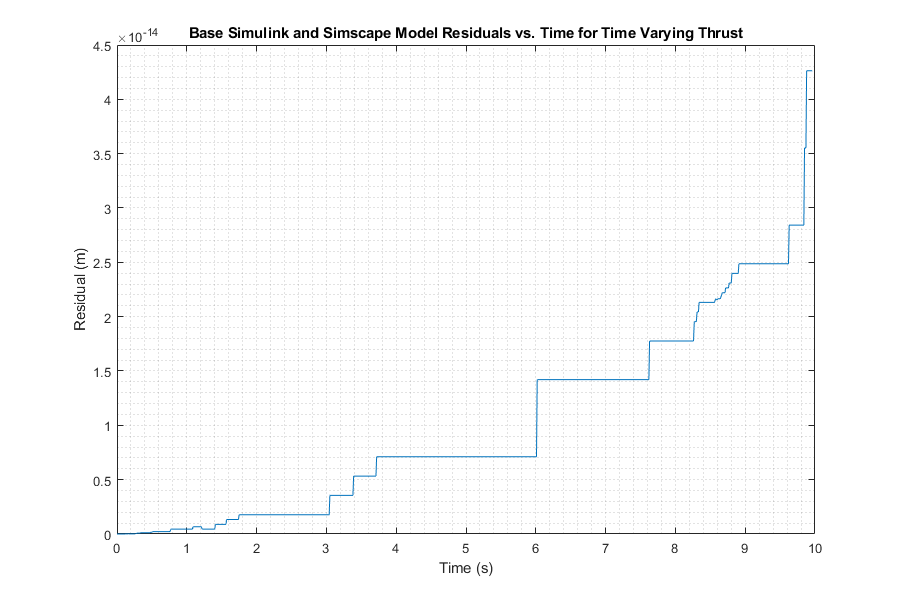

figure("Position", [0, 0, 900, 600])
% matlab will cover up the scientific notation of the y axis if it is larger. Excellent design mathworks.
plot(s2.out.sdat{1}.Values.y-s2.out.sdat{2}.Values.y)
title("Base Simulink and Simscape Model Residuals vs. Time for Time Varying Thrust")
ylabel("Residual (m)")
xlabel("Time (s)")
grid minor

The above residuals between the two models is promising. The maximum residual between the two models is approximatly $10\;x\;{10}^{-13}$ which is very reasonable for model. Next a look at the energy conservation.

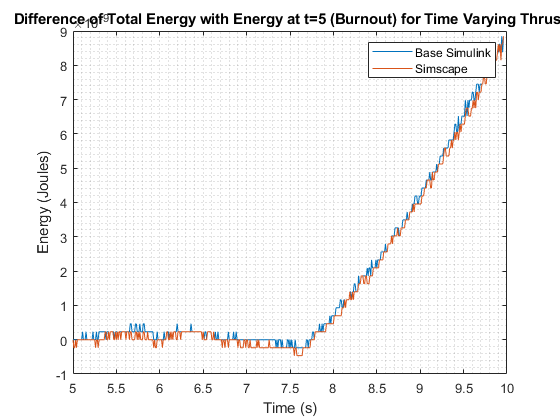

figure()
% the figure wouldn't even change size for me :(

[energyDQ, energySC] = energy(s2);

tEN      =     s1.t(s1.t >= 5);
energyDQ = energyDQ(s1.t >= 5);
energySC = energySC(s1.t >= 5);

figure()
plot(tEN, energyDQ - energyDQ(1), tEN, energySC - energySC(1))
legend("Base Simulink", "Simscape")
xlabel("Time (s)")
ylabel("Energy (Joules)")
grid minor
title("Difference of Total Energy with Energy at t=5 (Burnout) for Time Varying Thrust")

This shows that the total error between the energy at burnout and the maximum deviation afterwards is near ${9\mathrm{x10}}^{-9}$. This is very small, and is an acceptable result. The cumulative RSS errors are shown below.

base_simulink_cumulative_energy_error_constant = sqrt(sum((energyDQ - energyDQ(1)).^2))

base_simulink_cumulative_energy_error_constant = 6.9830e-08

simscape_cumulative_energy_error_constant = sqrt(sum((energySC - energySC(1)).^2))

simscape_cumulative_energy_error_constant = 6.7961e-08

Unlike the case with constant thrust there is a slight variation between the two models, but it is minimal. This is most likely due to more moving parts accentuating the internal differences of the Simscape model. But with these figures, it is safe to say that these models are verified for both constant thrust, and time-varying thrust. This does not nesscessarily mean they are accurate to the real world, but it does mean they are consistent with theoretical results and with each other. The next step to take would be to validate the models with real-world data.

function [energyDQ, energySC] = energy(data)
% Calcaultes the energy vs time

% simscpe = simscape model
% diffeq = diff eq = state variables simulink model
% the technical debt of meaningless variable names

% KE
diffeq. ke = 1/2 * (data.xdS.^2 + data.ydS.^2) * 1000;
simscpe.ke = 1/2 * (data.xdC.^2 + data.ydC.^2) * 1000;

% GPE
diffeq. gpe = data.yS * 10 * 1000;
simscpe.gpe = data.yC * 10 * 1000;

energyDQ = diffeq.ke + diffeq.gpe;
energySC = simscpe.ke + simscpe.gpe;
end